# Substitution

[⇦ Overview](matlab: OpenOverview)

A thorough understanding of the integral as an antiderivative can only take you so far. Just as with derivatives, there are integration rules that can be built through the combination of functions as well. The method of substitution that will be discussed in this live script applies to nearly every integral you will ever calculate. In fact, you will likely forget that you are even applying it in some cases because it will become so natural to use!

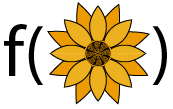

The method of substitution allows you to replace a complicated integral with a simpler one.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

clear
 

## **Practice using substitution**

Rewrite each of the following integrals in terms of the new variable provided by the substitution function,$\displaystyle \int f(g(x))g'(x)dx = \int f'(g)\; dg.$. Then solve the integral.

### **Exercise 1**

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

First, find the derivative of $g(x)$ with respect to $x$:

gprime = @(x) x;

What is the new measure going to be in terms of $g$?

NewMeasure = "dx";

If we define $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\cdot \text{New Measure}$, what is $f(g)$?

fa = @(g) g;

Calculate the function $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$.

answer = @(x,C) x;
check1a(gprime,fa,NewMeasure,answer);
 

  **Note: **In many textbooks it is common to use a variable $u$ in place of the variable $g$ or even to call this method $u$-substitution. 

### **Exercise 2**

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$ 

Calculate the derivative $u'(t)$.

uprime = @(t) t;

Calculate the new bounds and new measure for the integral in terms of $u$. 

ua = 1;
gb = 3;
NewMeasure = "dt";

If we define $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot \text{New Measure}$, what is $f(u)$?

f = @(u) u;

Calculate the function $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$.

answer =  0;
check1b(uprime,f,ua,gb,NewMeasure,answer);
 

### **Exercise 3**

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

Remember that $e^x$ is written as `exp(x)` in MATLAB.

gprime = @(r) r;
NewMeasure = "dr";

If we define $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \text{New Measure}$,

fc = @(q) q;
answer = @(r,C) r;
check1c(gprime,fc,NewMeasure,answer);
 

### **Exercise 4**

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

gprime = @(w) w;
ga = -1;
gb = 2;
measure = "dw";

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot \text{New Measure},$

fb = @(g) g;

This result is still not immediately computable, so let's make another substitution with $u(g) = \ln(g)$. Remember that $\ln(g)$ is written `log(g)` in MATLAB.

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot \text{Next New Measure},$

ua = -1;
ub = 2;
nextMeasure = "dw";
fu = @(u) u;

Putting everything together, compute the result:

answer =  0;
check1d(gprime,fb,ga,gb,measure,nextMeasure,ua,ub,fu,answer);
 

## Practice Randomized Substitution Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear errorCount totSubProbs totAttempts adjustcount lastFive myFun varChoice   
syms t r x z C                       % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totSubProbs = 0;                    % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Substitution Practice.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totSubProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = genProbType(varOpts,1);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totSubProbs = totSubProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

myAnswer = r;     % User-defined solution, default value r
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totSubProbs, ...
    adjustCount,myFun,varChoice,myAnswer,1,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
analyzeResults(totSubProbs,errorCount,totAttempts,adjustCount,lastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Substitution" in the Integrals section. The app will open in a new window.

[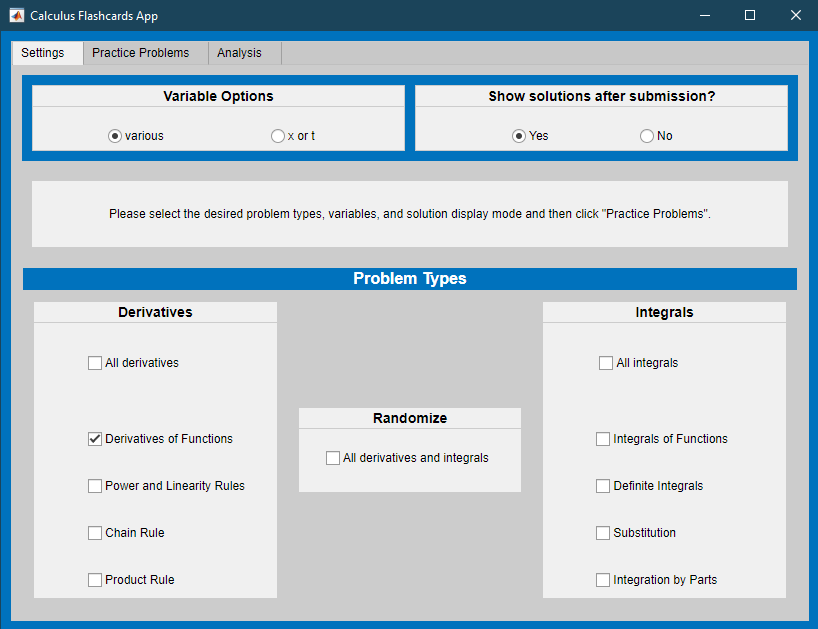](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

% % Practice Problem Generating Functions

function analyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

function [lastFive,errorCount] = check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = genProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
switch probType
    case 1 % Simple derivative
        syms f(x) g(x) x F(x) 
        [f(x),prevFuncType] = genFunDiff([1 3],x,[1 10],0);
        g(x) = genFunDiff([1 5],x,[5 10],prevFuncType);
        myFun = diff(f(g(varChoice)),varChoice);
        % Display the integral problem
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

function [myFunc,type] = genFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t+d);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t+d);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t+d);
    case 10
        f(t) = a*cos(b*t+d);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t+d);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t+d);
end
myFunc = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,probType,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    if length(totProbs)>1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        if length(totProbs) > 1
            [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
        else
            [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        end
    end
else
    if length(totProbs) > 1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        % check1 is defined in Helper Functions
        % check1 generates correct answers by differentiating myFun with respect to varChoice and compares
        % the result to myAnswer before updating the integer errorCount and matrix lastFive
    end
end
end

**Exercise 1 Solutions**

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

function check1a(gp,fsub,newMeasure,soln)
syms C x g f d 
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
meas = "dg";
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && newMeasure == "dx" && isequal(soln(x,C),x)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = newMeasure == meas;
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        disp("Correct.")
        displayFormula("dg/dx = gpans")
    else
        disp("You do not have the correct function for g'(x).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(g)")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"x")
        disp("The new measure should be in terms of g.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct.")
        displayFormula("int(f,x) = correctAns")
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$

function check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u f d
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
meas = "du";
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && newMeasure == "dt" && soln == 0
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = newMeasure == meas;
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        disp("Correct.")
        displayFormula("du/dt = gpans")
    else
        disp("You do not have the correct function for u'(t).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(u)")
    end
    if a5 && a6
        disp("You have the correct values for the bounds of the integral.")
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound.")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"t")
        disp("The new measure should be in terms of u.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct, the value of this integral is "+double(correctAns))
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Please try again.")
    end
end
end

c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

function check1c(gp,fsub,newMeasure,soln)
syms C x r q f d 
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
meas = "dq";
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && newMeasure == "dr" && isequal(soln(r,C),r)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = newMeasure == meas;
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        disp("Correct.")
        displayFormula("dq/dr = gpans")
    else
        disp("You do not have the correct function for q'(r).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    else
        disp("You do not have the correct function for f(q)")
    end
    if a3
        disp("Correct. The new measure is "+ meas)
    elseif contains(newMeasure,"r")
        disp("The new measure should be in terms of q.")
    else
        disp("Incorrect measure.")
    end
    if a4
        disp("Correct.")
        displayFormula("int(f,r) = correctAns")
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

function check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g f u dg du
% First substitution
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
comb1 = fg(g)*dg;
gaVal = ut(-1);
gbVal = ut(2);
% Second substitution
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
comb2 = fu(u)*du;
meas = "dg";
meas2 = "du";
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub,g) && ua == -1 && ub == 2 && newMeas1 == "dw" && soln == 0 ...
        && newMeas2 == "dw" && ua2 == -1 && ub2 == 2 && fusub == u
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = newMeas1 == meas;
    a2o3 = isAlways(fgsub(g)*str2sym(newMeas1)==comb1,"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = newMeas2 == meas2;
    a8 = isequal(fu(t),fusub(t));
    a7o8 = isAlways(fusub(u)*str2sym(newMeas2)==comb2,"Unknown","false");
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        disp("Correct.")
        displayFormula("dg/dw = gpans")
    else
        disp("You do not have the correct function for g'(w).")
    end
    if a2
        disp("Correct.")
        displayFormula("f = fg")
    elseif a2o3
        disp("Yes, the first integrand is ")
        displayFormula("f = fg*dg")
    else
        disp("You do not have the correct function for f(g)")
    end
    if a5 && a6
        disp("You have the correct values for the bounds of the first integral.")
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the first integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the first integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the first integral.")
    end
    if a3
        disp("Correct. The new measure for the first integral is "+ meas)
    elseif contains(newMeas1,"w")
        disp("The new measure should be in terms of g.")
    elseif a2o3
        disp("You have a correct integrand and measure for the first integral," + ...
            " but there is more than one way to break it down. What if the measure is simply dg?")
    else
        disp("Incorrect measure.")
    end
    if a9 && a10
        disp("You have the correct values for the bounds of the second integral.")
    elseif ~a9 && ~a10
        disp("You have not calcuated the correct values for the bounds of the second integral.")
    elseif a9
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the second integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the second integral.")
    end
    if a7 && a8
        disp("Correct. The new measure for the second integral is "+ meas + " and the integrand is")
        displayFormula("f = fu")
    elseif a7o8
        disp("Correct, but there is more than one way to break it down. What if the measure in the second integral is simply du?")
    elseif contains(newMeas2,"g") || contains(newMeas2,"w")
        disp("The new measure should be in terms of u.")
    elseif a7 && ~a8
        disp("Correct measure, but incorrect integrand in the second integral.")
    elseif ~a7 && a8
        disp("Incorrect measure, but correct integrand in the second integral.")
    else
        disp("Incorrect measure and incorrect integrand in the second integral.")
    end 
    if a4
        disp("Correct, the value of this integral is ")
        displayFormula("int(f,u)==correctAns(w,C)")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~((a2&a3)|a2o3) ~a4 ~a5 ~a6 ~((a7&a8)|a7o8)])
        disp("Please try again.")
    end
end
end